# 1 Modelação não linear de pêndulo invertido

#### Model variables

M = 0.5;    %kg
m = 0.214;  %kg
b = 0.2;    % Ns/m
c = 0.0026; % Ns/m
I = 0.0051; % Kg.m² same as J
L = 0.275;  %m
g = 10;     %m/s²

## a) Identify the system analytical equations

SOURCE

[https://ctms.engin.umich.edu/CTMS/index.php?example=InvertedPendulum&section=SystemModeling](https://ctms.engin.umich.edu/CTMS/index.php?example=InvertedPendulum&section=SystemModeling)

Adaptations required

- $L_{\;\textrm{source}} =\frac{L_{\;\textrm{system}} }{2}$; This is directly compensated by the fact that their mass is all on the edge of the rod while ours is distributed along the rod's length.

- 
$$\theta_{\textrm{system}} =\phi_{\textrm{source}\;\;} +\pi \;\left\lbrack \textrm{rad}\right\rbrack$$


- Our system accounted for angular friction between the rod hole and the bearing(highlighted in the angular velocity equation)

### Linear velocity equation

### 
$$\left(M+m\right)\ldotp \ddot{x} =F-B\dot{x} +\textrm{mL}\ddot{\ldotp \theta } \ldotp \cos \left(\theta \right)-\textrm{mL}\ddot{\theta} \ldotp \sin \left(\theta \right)$$


### Angular velocity equation

## 
$$\left(I+\textrm{mL²}\right)\ldotp \ddot{\theta} =\textrm{mL}\ddot{x} \cos \left(\theta \right)-\mathit{\mathbf{C}}\dot{\theta} +\textrm{mgLsin}\left(\theta \right)$$


The added term for angular friction is C.theta.

## b) Implement a)'s model in Simulink

Done in simulink

## c) Simulate the model with a small disturbance in F

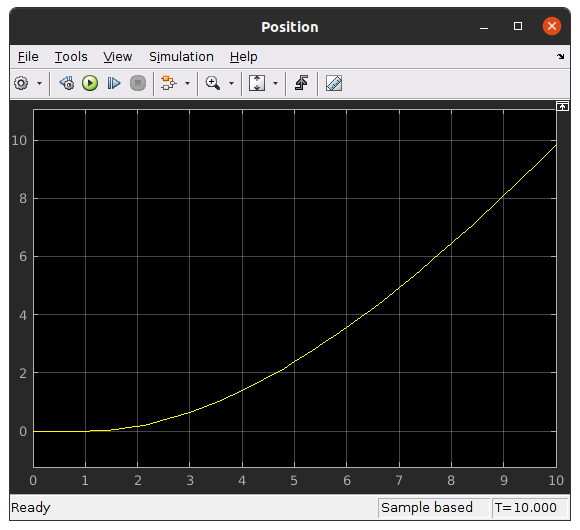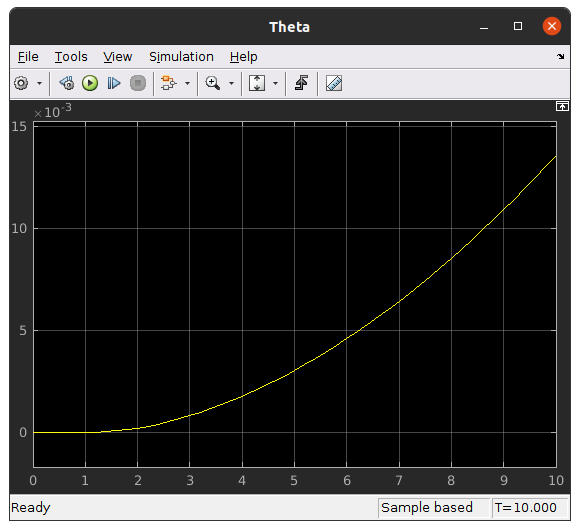

This is the result of a step of amplitude 0.5N, a small disturbance,starting at 1s.

This is the graph of position and angle over time.

We can see both are stable until the system reaches a certain point where our approximations of $\theta \approx 0$ are no longer valid and then the instability compounds into infinity.

# 2 Modelação linear de pêndulo invertido

## a) Identify valid approximations for $\theta \approx 0$ 

Here we want to find an approximated model of a lower order that still is fit to simulate our system. Since when vertical the angular deltas are quite small, it should be reasonable to consider approximations derived of $\theta \approx 0$.

A good way to do this while keeping the system linear is to use the Taylor's Expansion up to the first derivative (in order to keep the system linear as higher order expansions are more accurate but aren't linear).

Source : [https://en.wikipedia.org/wiki/Taylor_series](https://en.wikipedia.org/wiki/Taylor_series)


$$\begin{array}{l}
\cos \left(\theta \right)\approx 1\\
\sin \left(\theta \right)\approx \theta \\
\theta \approx 0\\
\dot{\theta} \approx 0
\end{array}$$


## b) Identify the linearized system equations

### Linear velocity equation - Linearized

### 
$$\left(M+m\right)\ldotp \ddot{x} =F-B\dot{x} +\textrm{mL}\ldotp \ddot{\theta}$$


### Angular velocity equation - Linearized

## 
$$\left(I+\textrm{mL²}\right)\ldotp \ddot{\theta} =\textrm{mL}\ddot{x} -\mathit{\mathbf{C}}\dot{\theta}$$


We just used those approximations in the non linear terms, in order to preserve the best relation possible to the analytical model.

## c) Implement a state space representation of the system, with force as input and position and angle as output.

A=[(-(M+m)*c)/(I*(M+m)+(M*m*L^2)), (-m*L*b)/(I*(M+m)+(M*m*L^2)), (m*g*L)/(I*(M+m)+(M*m*L^2)), 0;
    (-c*m*L)/(I*(M+m)+(M*m*L^2)), (-(I+m*L^2)*b)/(I*(M+m)+(M*m*L^2)), (m*m*g*L^2)/(I*(M+m)+(M*m*L^2)), 0;
    1, 0, 0, 0;
    0, 1, 0, 0];

B=[(m*L)/(I*(M+m)+(M*m*L^2));
   (I+m*L^2)/(I*(M+m)+(M*m*L^2));
   0;
   0];

C=[0, 0, 1, 0;
   0, 0, 0, 1];

D=[0;
    0];

% This doesn't include bearing friction

% p = I*(M+m)+M*m*L^2; %denominator for the A and B matrices
% 
% A = [0      1              0           0;
%      0 -(I+m*L^2)*b/p  (m^2*g*L^2)/p   0;
%      0      0              0           1;
%      0 -(m*L*b)/p       m*g*L*(M+m)/p  0];
% B = [     0;
%      (I+m*L^2)/p;
%           0;
%         m*L/p];
% C = [1 0 0 0;
%      0 0 1 0];
% D = [0;
%      0];
sys_ss = ss(A,B,C,D);
[num dem] = ss2tf(A,B,C,D)

num =          0         0    5.0156   -0.0000   -0.0000
         0         0    1.8140    0.2216  -76.1774


dem =     1.0000    0.5210  -50.1122  -15.2355         0


## d) Identify the system transfer function theta/f

We can use the function ss2tf to extract a transfer function from the state space.

sys_tf_pos = tf(num(1,:),dem)

sys_tf_pos =
 
   5.016 s^2 - 5.257e-15 s - 1.88e-15
  -------------------------------------
  s^4 + 0.521 s^3 - 50.11 s^2 - 15.24 s
 
Continuous-time transfer function.



sys_tf_angle = tf(num(2,:),dem)

sys_tf_angle =
 
      1.814 s^2 + 0.2216 s - 76.18
  -------------------------------------
  s^4 + 0.521 s^3 - 50.11 s^2 - 15.24 s
 
Continuous-time transfer function.



## e) Verifify stability/instability

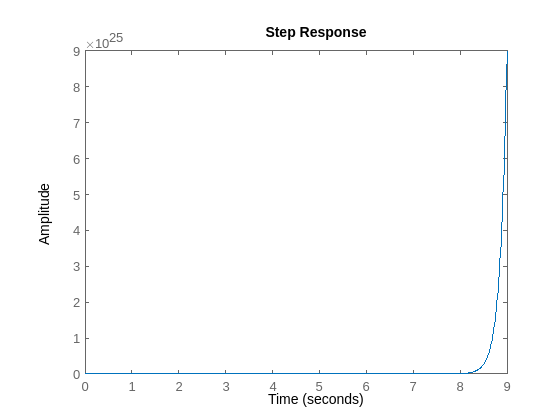

step(sys_tf_pos)

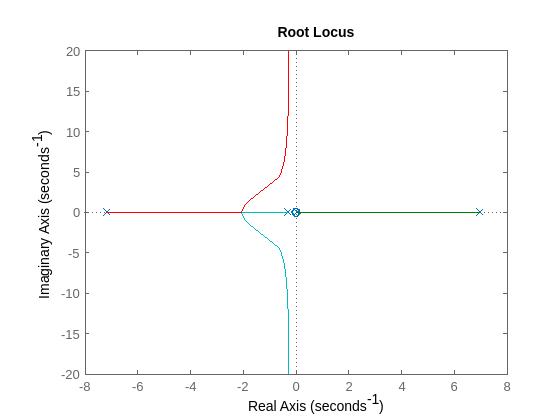


rlocus(sys_tf_pos);

The system is unstable.

## f) Simulate the system given a small disturbance force

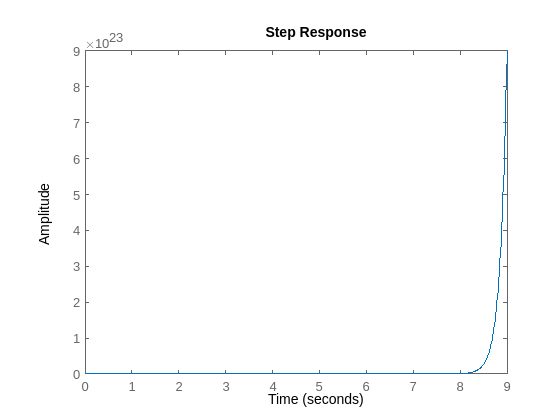

opt = stepDataOptions('StepAmplitude',0.01);
step(sys_tf_pos,opt)

This simulates the response of a step of amplitude of 0.05N.

# 3 Projeto e controlo de pêndulo invertido

## a) Identify a diagram block that could be used to determine the system transfer function using the best approximation from the last assignment.

- The chosen method for the approximation will be the Simulink approach,which is based on a second order model built on real data using *tfest.*

Manually importing the transfer function from the previous script:

s = tf('s');
G = 1.07e4/(s^2+195.6*s+1.07e4) % p1p2/(s+p1)(s+p2) clearly not this format

G =
 
          10700
  ---------------------
  s^2 + 195.6 s + 10700
 
Continuous-time transfer function.



Since our approximations in the previous assignment don't have the format p1p2/(s+p1)(s+p2), we will use the transfer function derived from the state space representation here calculated on this LiveScript.

zpk(sys_tf_angle)

ans =
 
      1.814 (s+6.542) (s-6.42)
  --------------------------------
  s (s-6.976) (s+7.193) (s+0.3036)
 
Continuous-time zero/pole/gain model.



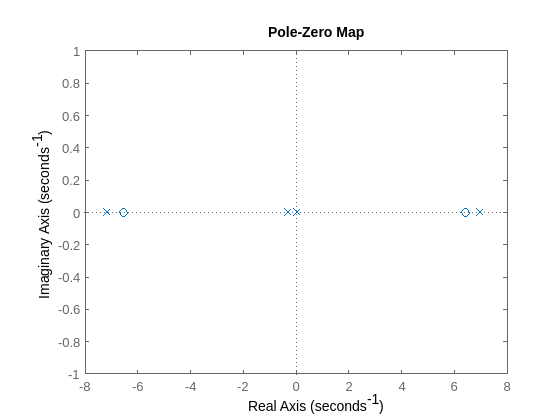

pzmap(sys_tf_angle)

## b) Analyse the possibility of controlling the system with a P controller.

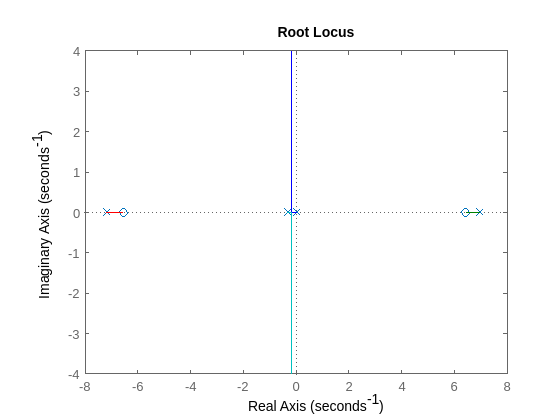

rlocus(sys_tf_angle);

Rlocus applies a proportional gain to the system. We can see the systm still isn't stable as there is a pole still past the imaginary axis.

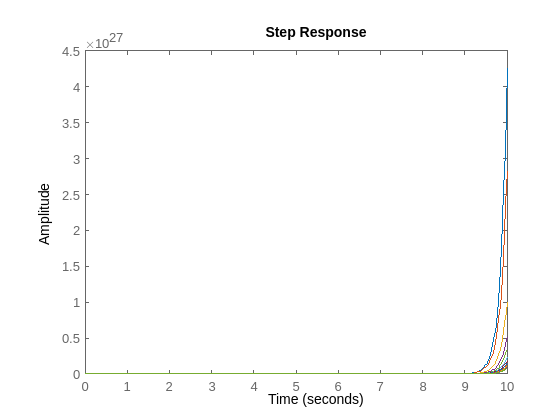

 
for k=1:25:300
    step(feedback(k*sys_tf_angle,1))
    hold on;
end
hold off;

For any given K, as expected, the system gets out of control.

## c) Analyse the possibility of controlling the system with a PI controller.

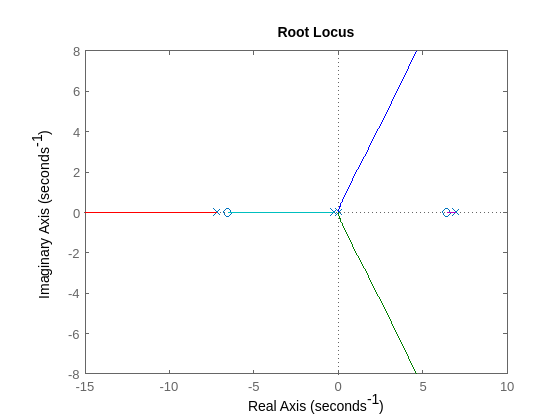

C_PI = 1/s;
rlocus(1/s * sys_tf_angle)

Still no luck.

## d) Analyse the possibility of controlling the system with a PID controller.

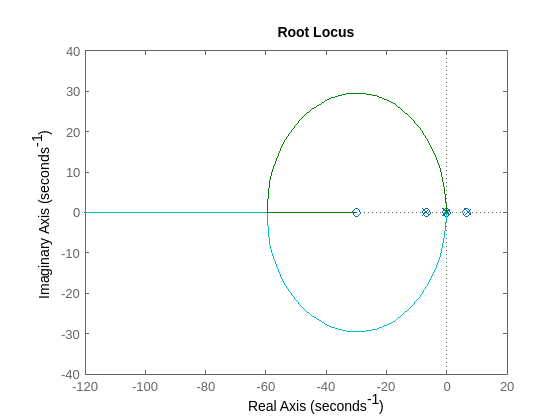

b = 30; %% zero position of the derivative controller

C_PID = C_PI + (s+b);
%% Again, to see rlocus stats, gotta execute the command in the command window
rlocus(C_PID* sys_tf_angle)

Kp = 70;
controlled_system = feedback(Kp * C_PID* sys_tf_angle,1)

controlled_system =
 
                                         
  127 s^4 + 3825 s^3 - 4740 s^2          
                                         
                        - 1.6e05 s - 5332
                                         
  ---------------------------------------
                                         
  s^5 + 127.5 s^4 + 3775 s^3 - 4755 s^2  
                                         
                        - 1.6e05 s - 5332
                                         
 
Continuous-time transfer function.



This is just to show the closed loop transfer function

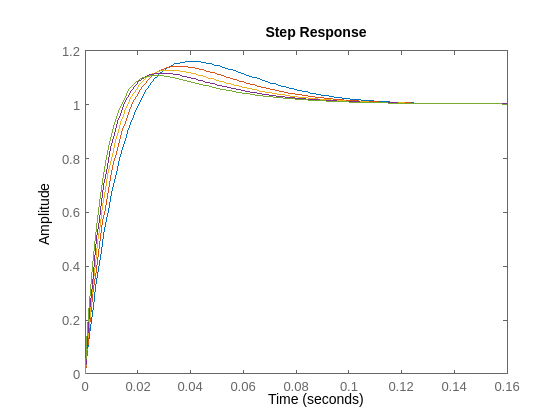


for Kp=50:10:90
    controlled_system = feedback(Kp * C_PID* sys_tf_angle,1);
    step(controlled_system);
    hold on;
end
hold off;

Here we can see how smaller gains have higher overshoot while big gains tend to offer a better response overall.

So here the process for tuning is : adjust the zero, see the gain range on rlocus where the branch is on the real axis ( 0 overshoot, which is ideal) and plot the various step responses.

Rinse and repeat to figure out a good value.

b = 30 and K gains from 60 to 90 seem like adequatte. If the zero is smaller then the effect of the branch which starts at the real side doesn't seem to get diminuished and the system gets out of control.